# Instance Space Analysis: A toolkit for the assessment of algorithmic power

**Instance Space Analysis** is a methodology for the assessment of the strengths and weaknesses of an algorithm, and an approach to objectively compare algorithmic power without bias introduced by restricted choice of test instances. At its core is the modelling of the relationship between structural properties of an instance and the performance of a group of algorithms. Instance Space Analysis allows the construction of **footprints** for each algorithm, defined as regions in the instance space where we statistically infer good performance. Other insights that can be gathered from Instance Space Analysis include:

- Objective metrics of each algorithm’s footprint across the instance space as a measure of algorithmic power;

- Explanation through visualization of how instance features correlate with algorithm performance in various regions of the instance space;

- Visualization of the distribution and diversity of existing benchmark and real-world instances;

- Assessment of the adequacy of the features used to characterize an instance;

- Partitioning of the instance space into recommended regions for automated algorithm selection;

- Distinguishing areas of the instance space where it may be useful to generate additional instances to gain further insights.

The unique advantage of visualizing algorithm performance in the instance space, rather than as a small set of summary statistics averaged across a selected collection of instances, is the nuanced analysis that becomes possible to explain strengths and weaknesses and examine interesting variations in performance that may be hidden by tables of summary statistics.

This live script is a **demonstration** of the [MATLAB tools](https://github.com/andremun/InstanceSpace) developed for the automated construction of an Instance Space. These are the `trainIS.m` and `testIS.m` functions, the settings from the `example.m` script, and associated subroutines. The objective is to explain to the user what the effects of the different options are being provided to the system. Not all functionalities from `trainIS.m` and `testIS.m`are demonstrated in this script, only those that have the highest impact on results. Understanding what each block does greatly helps in the usage of the [MATILDA web tool](https://matilda.unimelb.edu.au/).

**DISCLAIMER: The code, including this live script, is in constant evolution. In occasions new features will be added that may result in crashes. If you find issues, let us know ASAP through the contact methods described at the end of this live script.**

## **Installation Instructions**

The only requirement for the software to run is to have a current version of [MATLAB](http://www.mathworks.com/), with the [Communications](https://au.mathworks.com/products/communications.html), [Financial](https://au.mathworks.com/products/finance.html), [Global Optimization](https://au.mathworks.com/help/gads/index.html), [Optimization](https://au.mathworks.com/products/optimization.html), and [Statistics and Machine Learning](https://au.mathworks.com/help/stats/index.html) toolboxes installed. It has been tested and known to work properly in version r2018b. Earlier versions may fail to support several functions being used.

## **Training the Instance Space model**

The construction of the Instance Space is handled by the `trainIS.m` function. This is by far, the most complex process in the Instance Space Methodology. To make it more manageable, it has been organized as a processing pipeline with six main steps, as illustrated below. On the next sections, we examine each one of these steps.

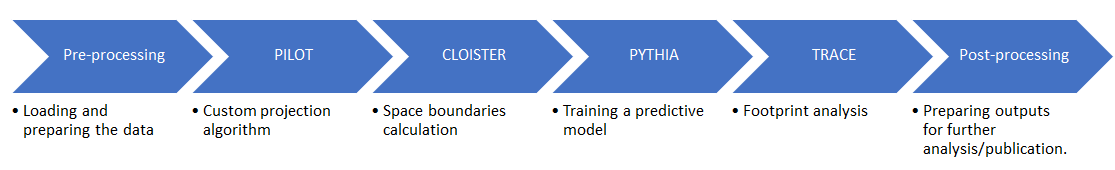

### Pre-processing: Loading and preparing the data

#### Setting up the environment and loading the training data

`trainIS.m` requests the location of a `'metadata.csv'` file as the variable `'rootdir'`, which is its only parameter. This is set up in the `example.m` script as: 

rootdir = './trial/';

This file should contain a table where each row corresponds to a problem instance, and each column must strictly follow the naming convention mentioned below:

- **instances **instance identifier - We expect instance identifier to be of type `'String'`. This column is mandatory.

- **source** instance source - This column is optional

- **feature_name **The keyword `'feature_'` concatenated with feature name. For instance, if feature name is `'density'`, header name should be mentioned as `'feature_density'`. If name consists of more than one word, each word should be separated by `'_'` (spaces are not allowed). There must be more than two features for the software to work. We expect the features to be of the type `'Double'`.

- **algo_name **The keyword `'algo_'` concatenated with algorithm name. For instance, if algorithm name is `'Greedy'`, column header should be` 'algo_greedy'`. If name consists of more than one word, each word should be separated by` '_'` (spaces are not allowed). You can add the performance of more than one algorithm in the same `.csv`. We expect the algorithm performance to be of the type `'Double'`.

Moreover, empty cells, `NaN` or null values are allowed but not recommended. If they exist, they should be a infimal minority in the data. We expect you to handle missing values in your data before processing. **Common mistakes while preparing the data are**: to use `NA` instead of `NaN`, to have Excel error codes such as `'#REF!'`, `'#NULL!'`, or `'#DIV/0!'`, or empty rows. This results in columns being identified as `'String'` instead of `'Double'` leading to crashes. All data will be stored within the `'model'` structure, within the `'data'` field.

Within `trainIS.m` the section that loads the data is the following block:

datafile = [rootdir 'metadata.csv'];
Xbar = readtable(datafile);
varlabels = Xbar.Properties.VariableNames;
isname = strcmpi(varlabels,'instances');
isfeat = strncmpi(varlabels,'feature_',8);
isalgo = strncmpi(varlabels,'algo_',5);
issource = strcmpi(varlabels,'source');
model.data.instlabels = Xbar{:,isname};
if isnumeric(model.data.instlabels)
    model.data.instlabels = num2cell(model.data.instlabels);
    model.data.instlabels = cellfun(@(x) num2str(x),model.data.instlabels,...
                                    'UniformOutput',false);
end
if any(issource)
    model.data.S = categorical(Xbar{:,issource});
end
model.data.X = Xbar{:,isfeat};
model.data.Y = Xbar{:,isalgo};
model.data.featlabels = varlabels(isfeat);
model.data.Xraw = model.data.X;
model.data.Yraw = model.data.Y;
model.data.algolabels = varlabels(isalgo);
model.data.featlabels = strrep(model.data.featlabels,'feature_','');
model.data.algolabels = strrep(model.data.algolabels,'algo_','');
disp('Data has been succesfuly loaded. This is the head of the data table.')
disp(Xbar(1:10,:));

#### Identifying the type of performance measure

To construct the models and a binary performance measure, `trainIS.m` requires setting these options in the `example.m`script:

- `opts.perf.MaxPerf` determines whether the algorithm performance values provided are **efficiency** measures that should be **maximized** (set as `TRUE`), or **cost** measures that should be **minimized** (set as `FALSE`). It corresponds to the `Optimization Criteria` menu in the [web interface](https://matilda.unimelb.edu.au/matilda/data-analytics).

- `opts.perf.AbsPerf` determines whether good performance is defined **absolutely**, e.g., misclassification error is lower than a 20%, (set as `TRUE`), or if it is defined **relatively** to the best performing algorithm, e.g., misclassification error is within at least 5% of the best algorithm, (set as `FALSE`). It corresponds to the `Performance Criteria` menu in the [web interface](https://matilda.unimelb.edu.au/matilda/data-analytics).

- `opts.perf.epsilon` is the threshold used to calculate good performance. It must be of the type `'Double'`. It corresponds to the `Performance Threshold` field in the [web interface](https://matilda.unimelb.edu.au/matilda/data-analytics).

opts.perf.MaxPerf = false;  % True if Y is a performance measure to maximize,
                            % False if it is a cost measure to minimise.
opts.perf.AbsPerf = true;   % True if an absolute performance measure, 
                            % False if a relative performance measure
opts.perf.epsilon = 0.20;   % Threshold of good performance

Setting these options incorrectly often leads to unusual results. For example, Whenever **absolute** performance is used, `opts.perf.epsilon` should be within the range of the performance measure, which may or may not be `[0,1]`as expected for **relative** performances.

Moreover, `trainIS.m` calculates a weight for each instance based on the difference in performance between the algorithm's performance on the instance and the average performance across all algorithms and instances. This weight can be used to make the training of the predictive models cost-sensitive.

Within `trainIS.m` the section that processes the binary performance is the following block:

msg = '-> An algorithm is good if its performace is ';
if opts.perf.MaxPerf
    Yaux = model.data.Y;
    Yaux(isnan(Yaux)) = -Inf;
    [rankPerf,rankAlgo] = sort(Yaux,2,'descend');
    model.data.bestPerformace = rankPerf(:,1);
    model.data.P = rankAlgo(:,1);
    if opts.perf.AbsPerf
        model.data.Ybin = Yaux>=opts.perf.epsilon;
        msg = [msg 'higher than ' num2str(opts.perf.epsilon)];
    else
        % One is good, zero is bad
        model.data.Ybin = bsxfun(@ge,Yaux,(1-opts.perf.epsilon).*model.data.bestPerformace);
        msg = [msg 'within ' num2str(round(100.*opts.perf.epsilon)) '% of the best.'];
    end
else
    Yaux = model.data.Y;
    Yaux(isnan(Yaux)) = Inf;
    [rankPerf,rankAlgo] = sort(Yaux,2,'ascend');
    model.data.bestPerformace = rankPerf(:,1);
    model.data.P = rankAlgo(:,1);
    if opts.perf.AbsPerf
        model.data.Ybin = Yaux<=opts.perf.epsilon;
        msg = [msg 'less than ' num2str(opts.perf.epsilon)];
    else
        model.data.Ybin = bsxfun(@le,Yaux,(1+opts.perf.epsilon).*model.data.bestPerformace);
        msg = [msg 'within ' num2str(round(100.*opts.perf.epsilon)) '% of the best.'];
    end
end
model.data.W = abs(model.data.Y-nanmean(model.data.Y(:)));
model.data.W(model.data.W==0) = min(model.data.W(model.data.W~=0));
model.data.W(isnan(model.data.W)) = max(model.data.W(~isnan(model.data.W)));
disp(msg);

#### Defining hard instances for the portfolio

We often define whether an instance is hard (or easy) for the portfolio in general. This is set up by the $\beta$ threshold, defined as  `opts.general.betaThreshold` in the `example.m` script, which should be in the `[0,1]` range. In general, we consider that if more than half of the algorithms are good, then the instance is easy. This option in `example.m` script controls this task:

opts.general.betaThreshold = 0.55;  % Beta-easy threshold

Within `trainIS.m` the section that identifies whether an instance is hard is the following block, which also determines the number of good algorithms, and if more than one best algorithm exists for an instance, it will pick one at random.

nalgos = size(model.data.Y,2);
bestAlgos = bsxfun(@eq,model.data.Y,model.data.bestPerformace);
multipleBestAlgos = sum(bestAlgos,2)>1;
aidx = 1:nalgos;
for i=1:size(model.data.Y,1)
    if multipleBestAlgos(i)
        aux = aidx(bestAlgos(i,:));
        model.data.P(i) = aux(randi(length(aux),1)); % Pick one at random
    end
end
model.data.numGoodAlgos = sum(model.data.Ybin,2);
model.data.beta = model.data.numGoodAlgos>opts.general.betaThreshold*nalgos;
disp(['-> For ' num2str(round(100.*mean(multipleBestAlgos))) '% of the instances there is ' ...
      'more than one best algorithm. Random selection was used to break ties.']);

#### Automated bounding and scaling

The toolkit implements simple routines to bound outliers and scale the data. **These routines are by no means perfect, and users should pre-process their data independently if preferred**. However, the automatic bounding and scaling routines should give some idea of the kind of results may be achieved. In general, we recommend that the data is transformed to become close to normally distributed due to the linear nature of PILOT's optimal projection algorithm. These options in the `example.m` script control these tasks:

- `opts.auto.preproc` turns on (set as `TRUE`) the automatic pre-processing.

- `opts.bound.flag` turns on (set as `TRUE`) data bounding. This sub-routine calculates the median and the interquartile range ([IQR](https://en.wikipedia.org/wiki/Interquartile_range)) of each feature and performance measure, and bounds the data to the median plus or minus five times the IQR. **This sub-routine often has issues with features that have low value diversity**, e.g., most of the instances have the exact same value. Depending of the user's knowledge of such features, it is recommended to: (a) eliminate the problematic features (b) disable this sub-routine by setting this value to `FALSE`.

- `opts.norm.flag` turns on (set as `TRUE`) scaling. This sub-routine scales into a positive range each feature and performance measure. Then it calculates a [box-cox transformation](https://en.wikipedia.org/wiki/Power_transform#Box%E2%80%93Cox_transformation) to stabilize the variance, and a [Z-transformation](https://en.wikipedia.org/wiki/Standard_score) to standardize the data. The result are features and performance measures that are close to normally distributed.

opts.auto.preproc = true;   % Automatic preprocessing on. 
                            % Set to false if you don't want any preprocessing
opts.bound.flag = true;     % Bound the outliers. True if you want to bound the outliers, 
                            % false if you don't
opts.norm.flag = true;      % Normalize/Standarize the data. True if you want to apply 
                            % Box-Cox and Z transformations to stabilize the variance and scale N(0,1)

Within `trainIS.m` the section that performs bounding and scaling is the following block:

if opts.auto.preproc
    if opts.bound.flag
        [model.data.X, model.bound] = boundOutliers(model.data.X);
    end
    if opts.norm.flag
        [model.data.X, model.data.Y, model.norm] = autoNormalize(model.data.X, model.data.Y);
    end
end

#### Running an small scale experiment

In occasions, we have a large (>1000) set of instances to be processed, which may take a while to complete. To avoid wasting time waiting for results without knowing if the settings are likely to produce successful outcomes, `trainIS.m` contains facilities to subsample the data. There are two basic ways to do a subsample, both of which are turned off by default. As such, **they are not demonstrated in this live script**. The first one is by randomly selecting a fraction of the data, while the second one is by giving a list of indexes. The following options in the `example.m` script control these tasks:

- `opts.selvars.smallscaleflag` (if set as `TRUE`) activates random selection of a fraction of the original data.

- `opts.selvars.smallscale` is the fraction taken from the original data, which should be in the `[0,1]` range.

- `opts.selvars.fileidxflag` (if set as `TRUE`) activates selection by indexing.

- `opts.selvars.fileidx` is the name of a `.csv` file that contains in one column the indexes of the instances to be taken. This may be useful if you want to make a more controlled experiment than just randomly selecting instances.

opts.selvars.smallscaleflag = false;     
opts.selvars.smallscale = 0.30;          
opts.selvars.fileidxflag = false;
opts.selvars.fileidx = '';

Another approach to do a small scale experiment is to select a subset of features or algorithms to process. This may be useful if you already know which features to use, or you want to test a subset of algorithms. This is done by listing the features and algorithms in the options `opts.selvars.feats` and `opts.selvars.algos `in the `example.m` script. **The examples below are only for reference and the values are not being used on this script**.

opts.selvars.feats = {'feature_Max_Normalized_Entropy_attributes',...
                      'feature_Normalized_Entropy_Class_Attribute',...
                      'feature_Nonlinearity_Nearest_Neighbor_Classifier_N4'};
opts.selvars.algos = {'algo_NB',...
                      'algo_CART',...
                      'algo_KNN',...
                      'algo_RBF_SVM',...
                      'algo_RandF'};

#### Automated feature selection

The toolkit implements simple routines to select features, given their cross-correlation and correlation to performance. Ideally, we want the smallest number of orthogonal and predictive features. **These routines are by no means perfect, and users should pre-process their data independently if preferred**. In general, we recommend using no more than 10 features as input to PILOT's optimal projection algorithm, due to the numerical nature of its solution and issues in identifying meaningful linear trends. The following options in the `example.m` script control these tasks:

- `opts.auto.featsel` turns on (set as `TRUE`) the automatic feature selection.

- `opts.corr.flag` turns on (set as `TRUE`) the selection by correlation between features and performance measures. This sub-routine calculates the [Pearson correlation coefficient](https://en.wikipedia.org/wiki/Pearson_correlation_coefficient) between the features and the performance. Then it takes its absolute value and sorts them from largest to lowest. Then, for each algorithm, it takes the top features as defined by the threshold. It automatically bounds itself to a minimum of 3 features. We recommend using this routine, particularly if the number of features is greater than 20.

- `opts.corr.threshold` correlation threshold indicating the top N features per algorithm that should be selected based on correlation with performance. It should be a value higher than 1.

- `opts.clust.flag` turns on (set as `TRUE`) the selection by clustering. It works by defining the [Pearson correlation coefficient](https://en.wikipedia.org/wiki/Pearson_correlation_coefficient) as a dissimilarity metric between features. Then, [k-means clustering](https://en.wikipedia.org/wiki/K-means_clustering) is used to identify groups of similar features. To select one feature per group, the algorithm first projects the subset of selected featurs into two dimensions using Principal Components Analysis ([PCA](https://en.wikipedia.org/wiki/Principal_component_analysis)) and then [Random Forests](https://en.wikipedia.org/wiki/Random_forest) to predict whether an instance is easy or not for a given algorithm. Then, the subset of features that gives the most accurate models is selected. This routine is potentially very expensive computationally due to the multiple layer training process. However, it is our current recommended approach to select the most relevant features. This routine tests all possible combinations if they are less than 1000 or uses the combination of a [Genetic Algorithm](https://en.wikipedia.org/wiki/Genetic_algorithm) and a Look-up table otherwise.

- `opts.clust.KDEFAULT` number of default clusters. The routine assumes at least 3 clusters and no more than the number of features. Ideally it should not be a value larger than 10.

- `opts.clust.SILTHRESHOLD` the routine uses [Silhouette analysis](https://en.wikipedia.org/wiki/Silhouette_(clustering)) to automatically infer the existing number of clusters. It must be a value between 0 and 1, preferably between 0.4 and 0.8. **You should experiment with this value to obtain the best results**.

- `opts.clust.NTREES` number of threes used by the Random Forest models.

- `opts.clust.MaxIter` number of iterations used to converge the k-means algorithm.

- `opts.clust.Replicates` number of repeats carried out of the k-means algorithm.

opts.auto.featsel = true;               % Automatic feature selectio on. 
                                        % Set to false if you don't want any feature selection.
opts.corr.flag = true;                  % Run feature selection by correlation 
                                        % between performance and features
opts.corr.threshold = 10;               % Top N features (by correlation) per 
                                        % algorithm that are selected
opts.clust.flag = true;                 % Run feature selection by clustering (Step 3)
opts.clust.KDEFAULT = 10;               % Default maximum number of clusters
opts.clust.SILTHRESHOLD = 0.7;          % Minimum accepted value for the average silhoute value
opts.clust.NTREES = 50;                 % Number of trees for the Random Forest 
                                        % (to determine highest separability in the 2-d projection)
opts.clust.MaxIter = 1000;
opts.clust.Replicates = 100;

Within `trainIS.m` the section that performs feature selection is the following block:

nfeats = size(model.data.X,2);
model.featsel.idx = 1:nfeats;
if opts.auto.featsel
    if opts.corr.flag
        [model.data.X, model.corr] = checkCorrelation(model.data.X, ...
                                                      model.data.Y, ...
                                                      opts.corr);
        model.data.featlabels = model.data.featlabels(model.corr.selvars);
        model.featsel.idx = model.featsel.idx(model.corr.selvars);
    end
    if opts.clust.flag
        [model.data.X, model.clust] = clusterFeatureSelection(model.data.X, ...
                                                              model.data.Ybin, ...
                                                              opts.clust);
        model.data.featlabels = model.data.featlabels(model.clust.selvars);
        model.featsel.idx = model.featsel.idx(model.clust.selvars);
    end
end

On the console output, you may observe the `Average silhouette value for each number of clusters`. This information will help you determine the best value of `opts.clust.SILTHRESHOLD`. You may analyze this result graphically by plotting the variable `model.clust.eva`.

plot(model.clust.eva);

In this example, as the data has been already cleaned up, the ideal number of features is 10.

### PILOT: Obtaining a two-dimensional projection

Projecting Instances with Linearly Observable Trends (PILOT) is a dimensionality reduction algorithm which aims to facilitate the identification of relationships between instances and algorithms by unveiling linear trends in the data, increasing from one edge of the space to the opposite. It does so by minimizing the error $	\| \mathbf{F} - \widehat{\mathbf{F}} \|^{2}_{F} + \| \mathbf{Y} - \widehat{\mathbf{Y}} \|^{2}_{F}$, where $\mathbf{F}$ and $\mathbf{Y}$are the matrix of features and algorithm performances, $\widehat{\mathbf{F}}$ and $\widehat{\mathbf{Y}}$are its estimates. In other words, the projection should be predictive of both the features and the performances. Details of this algorithm can be found in  ([Munoz et al. 2018](https://link.springer.com/article/10.1007/s10994-017-5629-5)). PILOT has two options to be set up in `example.m`:

- `opts.pilot.analytic` determines whether the **analytic** (set as `TRUE`) or the **numerical** (set as `FALSE`) solution to the dimensionality reduction problem should be used. We recommend leaving this setting as `FALSE`, due to the instability of the analytical solution due to possible poor-conditioning.

- `opts.pilot.ntries` number of iterations that the numerical solution is attempted.

opts.pilot.analytic = false;           % Calculate the analytical or numerical solution
opts.pilot.ntries = 5;                 % Number of attempts carried out by PBLDR

PILOT's function call within `trainIS.m` is:

model.pilot = PILOT(model.data.X, model.data.Y, model.data.featlabels, opts.pilot);

For this example, the resulting projection is:


$$	\left[
		\begin{array}{rr}
             0.2223 &   0.0612\\
    0.9270  &  0.0879 \\
    0.0318  & -0.3365\\
    0.2272  &  0.1497\\
   -0.2061  &  0.0380\\
    0.1761  & -0.1114\\
    0.2159  &  0.9730\\
   -0.2620   & 0.2985\\
		\end{array}%
		\right]^{\top}
\left[
		\begin{array}{l}
		    Max\_Normalized\_Entropy\_attributes\\
Normalized\_Entropy\_Class\_Attribute\\
Mean\_Mutual\_Information\_Attribute\_Class\\
ErrorRate\_Decision\_Node\\
WeightedDist\_StdDev\\
Collective\_Feature\_Efficiency\_F4\\
Fraction\_Points\_Class\_Boundary\_N1\\
Nonlinearity\_Nearest\_Neighbor\_Classifier\_N4
		\end{array}
		\right]
$$


Let's take some time to explore the results. The toolkit contains a library of functions callable through `scriptfcn`. Among them are prepared scatter plots for both continuous (`drawScatter`) and binary (`drawBinaryPerformance`) values. Let's observe the results for one of the features (`WeightedDist_StdDev`), which has an increasing trend from top-right to bottom-left.

scriptfcn;
figure;
ifeat = 5;
Xaux = (model.data.X-min(model.data.X,[],1))./range(model.data.X,1);
drawScatter(model.pilot.Z, Xaux(:,ifeat),strrep(model.data.featlabels{ifeat},'_',' '));

And compare with the performance measure (classification error) of the Classification and Regression Tree (CART) algorithm. First, as a continuous value.

figure;
ialgo = 4;
Yind = (model.data.Y-min(model.data.Y,[],1))./range(model.data.Y,1);
drawScatter(model.pilot.Z, Yind(:,ialgo),strrep(model.data.algolabels{ialgo},'_',' '));

Second, as the binary measure of good. We can observe that the feature and performance trends are reciprocal.

figure;
drawBinaryPerformance(model.pilot.Z, model.data.Ybin(:,ialgo), ...
                      strrep(model.data.algolabels{ialgo},'_',' '));

### CLOISTER: Finding the empirical bounds of the space

Correlated Limits of the Instance Space Theoretical or Experimental Regions (CLOISTER) is a heuristic algorithm that uses the correlation between features to determine experimental bounds of the space. It works by constructing all the possible combinations between the maximum and minimum values from each feature, and then using the [Pearson correlation coefficient](https://en.wikipedia.org/wiki/Pearson_correlation_coefficient) to determine whether a combination is feasible or not. CLOISTER has two options to be set up in `example.m`:

- `opts.cloister.cthres` Determines the maximum [Pearson correlation coefficient](https://en.wikipedia.org/wiki/Pearson_correlation_coefficient) that would indicate **non-correlated** variables. The **lower** this value is, the **more stringent** is the algorithm; hence, it would be less likely to produce a good bound.

- `opts.cloister.pval` Determines the p-value of the Pearson correlation coefficient that indicates no correlation.

opts.cloister.cthres = 0.7;
opts.cloister.pval = 0.05;

CLOISTER's function call within `trainIS.m `is:

model.cloist = CLOISTER(model.data.X, model.pilot.A, opts.cloister);

Let's observe the results for one of the features (`WeightedDist_StdDev`). The bounds indicate that there is enough slack area for new instances to exist.

figure;
drawScatter(model.pilot.Z, Xaux(:,ifeat),strrep(model.data.featlabels{ifeat},'_',' '));
line(model.cloist.Zecorr(:,1),model.cloist.Zecorr(:,2));

### PYTHIA: Building an oracle for algorithm selection

Named in honor of the Oracle of Delphi, PYTHIA trains a set of Support Vector Machine (SVM) classification models that predict whether an algorithm will perform well or not on a given instance. PYTHIA uses [fitcsvm](https://au.mathworks.com/help/stats/fitcsvm.html), MATLAB's implementation of a SVM, as such, it performs a number of operations automatically: (a) It produces resubstitution results using a stratified K-fold cross-validation partition, (b) it gives a probability for each instance of belonging to a given class, by fitting a posterior probability model, (c) it uses Bayesian Optimization to fine tune the SVM hyper-parameters $\left\{C,\gamma\right\}$, (d) can use cost-sensitive classification by weighting each instance, as described above. Depending of the number of instances in the training data, PYTHIA will use a Gaussian (≤1000 instances) or a polynomial (>1000) kernel. PYTHIA has two options to be set up in `example.m`:

- `opts.pythia.cvfolds` is the number of folds of the stratified cross-validation partition.

- `opts.pythia.useweights` determines whether **weighted** (set as `TRUE`) or **unweighted** (set as `FALSE`) classification is performed. It is set as `FALSE `as default.

opts.pythia.cvfolds = 5;
opts.pythia.useweights = false;

PYTHIA's function call within `trainIS.m` is:

model.pythia = PYTHIA(model.pilot.Z, model.data.Yraw, model.data.Ybin, ...
                      model.data.W, model.data.bestPerformace, model.data.algolabels, ...
                      opts.pythia);

Let's explore the results for the CART algorithm and compare them with the training data. The trained model has a CV accuracy of 92.9%, a precision of 94.7% and a recall of 95.4%.

figure;
drawBinaryPerformance(model.pilot.Z, model.pythia.Yhat(:,ialgo), ...
                      strrep(model.data.algolabels{ialgo},'_',' '));

### TRACE: Calculating the algorithm footprints

Triangulation with Removal of Areas with Contradicting Evidence (TRACE) is an algorithm used to estimate the area of good performance of an algorithm within the space. Such an area will have a density, instances per unit of area, and a purity, number of instances of good performance per number of instances, associated with it. When two or more algorithms share the same area of good performance, TRACE uses purity to determine which algorithm should keep that area. TRACE has one option to be set up in `example.m`, although in the future, minimum thresholds for density and purity will be activated.

- `opts.trace.usesim` makes use of the **actual** (set as `FALSE`) or **simulated** data from the SVM results (set as `TRUE`) to produce the footprints. In this example, we use simulated data.

opts.trace.usesim = true;           % Use the actual or simulated data to calculate the footprints

TRACE's function call within `trainIS.m` is:

if opts.trace.usesim
    model.trace = TRACE(model.pilot.Z, model.pythia.Yhat, model.pythia.selection0, ...
                        model.data.beta, model.data.algolabels, opts.trace);
else
    model.trace = TRACE(model.pilot.Z, model.data.Ybin, model.data.P, model.data.beta, ...
                        model.data.algolabels, opts.trace);
end

Let's explore the results for the CART algorithm and compare them with the simulation data. The footprint has an area of 54.5% of the space, with a relative density of 127.7% and a purity of 100%.

figure;
drawGoodBadFootprint(model.pilot.Z, ...
                     model.trace.good{ialgo}, ...
                     model.trace.bad{ialgo}, ...
                     model.pythia.Yhat(:,ialgo), ...
                     strrep(model.data.algolabels{ialgo},'_',' '));

### Post-processing: Preparing results for further analysis or publication

Finally, `trainIS.m` produces outputs for further analysis in the form of `.csv` and `.png` files, while the complete model structure is also stored into a `.mat` file. The options within `example.m` to control these functionalities are as follows; however, **they are not demonstrated in this script**.

- `opts.outputs.csv` This flag produces the output CSV files for post-processing and analysis. It is recommended to leave this setting as `TRUE`.

- `opts.outputs.png` This flag produces the output figures files for post-processing and analysis. It is recommended to leave this setting as `TRUE`.

- `opts.outputs.web` This flag produces the output files employed to draw the figures in MATILDA's web tools (click [here](https://matilda.unimelb.edu.au/matilda/newuser)to open an account). It is recommended to leave this setting as `FALSE`.

opts.outputs.csv = true;               %
opts.outputs.png = true;               %
opts.outputs.web = false;              % NOTE: MAKE THIS FALSE IF YOU ARE USING THIS CODE LOCALY
                                       % This flag is only useful if the system is being used 'online' 
                                       % through matilda.unimelb.edu.au

Moreover, all options used for generating the Instance Space are stored within the `model` structure to be used for further analysis.

model.opts = opts;

## Testing the Instance Space model

Once `trainIS.m` has completed, it will produce as output the `model` structure, which contains among other things: (a) All the training data, both in raw and pre-processed forms; (b) The outputs for all pre-processing steps for further debugging and analysis; (c) The projection matrix, obtained through PILOT; (d) the SVM prediction models and their statistics, such as accuracy, precision and recall; and (e) The footprints for good, bad and best performance and their statistics, such as area, density and purity. As such, `model` can be used to analyze unseen instances. This is the purpose of `testIS.m`, whose function we will explore in the following sections.

**DISCLAIMER: **`testIS.m`** is not as mature as its training counterpart. While bug-free, it lacks some functionalities that would make flexible enough for its intended tasks. However, it serves as an example of how to further work with the **`model`** structure can be carried out, if it is required.**

### Setting up the test data

The pre-processing steps of `testIS.m` mimic those of `trainIS.m`, but uses the results and options stored into `model` to make the results compatible. As such, we will not dwell on the description of the code below.

datafile = [rootdir 'metadata_test.csv'];
Xbar = readtable(datafile);
varlabels = Xbar.Properties.VariableNames;
isname = strcmpi(varlabels,'instances');
isfeat = strncmpi(varlabels,'feature_',8);
isalgo = strncmpi(varlabels,'algo_',5);
issource = strcmpi(varlabels,'source');
out.data.instlabels = Xbar{:,isname};
if isnumeric(out.data.instlabels)
    out.data.instlabels = num2cell(out.data.instlabels);
    out.data.instlabels = cellfun(@(x) num2str(x),out.data.instlabels,'UniformOutput',false);
end
if any(issource)
    out.data.S = categorical(Xbar{:,issource});
end
out.data.X = Xbar{:,isfeat};
out.data.Y = Xbar{:,isalgo};
nalgos = size(out.data.Y,2);
out.data.Xraw = out.data.X;
out.data.Yraw = out.data.Y;

if model.opts.perf.MaxPerf
    Yaux = out.data.Y;
    Yaux(isnan(Yaux)) = -Inf;
    [rankPerf,rankAlgo] = sort(Yaux,2,'descend');
    out.data.bestPerformace = rankPerf(:,1);
    out.data.P = rankAlgo(:,1);
    if model.opts.perf.AbsPerf
        out.data.Ybin = out.data.Y>=model.opts.perf.epsilon;
    else
        out.data.Ybin = bsxfun(@ge,out.data.Y,(1-model.opts.perf.epsilon).*...
                               out.data.bestPerformace); % One is good, zero is bad
    end
else
    Yaux = out.data.Y;
    Yaux(isnan(Yaux)) = Inf;
    [rankPerf,rankAlgo] = sort(Yaux,2,'ascend');
    out.data.bestPerformace = rankPerf(:,1);
    out.data.P = rankAlgo(:,1);
    if model.opts.perf.AbsPerf
        out.data.Ybin = out.data.Y<=model.opts.perf.epsilon;
    else
        out.data.Ybin = bsxfun(@le,out.data.Y,(1+model.opts.perf.epsilon).*out.data.bestPerformace);
    end
end
out.data.numGoodAlgos = sum(out.data.Ybin,2);
out.data.beta = out.data.numGoodAlgos>model.opts.general.betaThreshold*nalgos;

if model.opts.auto.preproc && model.opts.bound.flag
    himask = bsxfun(@gt,out.data.X,model.bound.hibound);
    lomask = bsxfun(@lt,out.data.X,model.bound.lobound);
    out.data.X = out.data.X.*~(himask | lomask) + bsxfun(@times,himask,model.bound.hibound) + ...
                                                  bsxfun(@times,lomask,model.bound.lobound);
end

if model.opts.auto.preproc && model.opts.norm.flag
    out.data.X = bsxfun(@minus,out.data.X,model.norm.minX)+1;
    out.data.X = bsxfun(@rdivide,bsxfun(@power,out.data.X,model.norm.lambdaX)-1,...
                                        model.norm.lambdaX);
    out.data.X = bsxfun(@rdivide,bsxfun(@minus,out.data.X,model.norm.muX),...
                                        model.norm.sigmaX);
    
    out.data.Y(out.data.Y==0) = eps; % Assumes that out.data.Y is always positive and higher than 1e-16
    out.data.Y = bsxfun(@rdivide,bsxfun(@power,out.data.Y,model.norm.lambdaY)-1,...
                                        model.norm.lambdaY);
    out.data.Y = bsxfun(@rdivide,bsxfun(@minus,out.data.Y,model.norm.muY),...
                                        model.norm.sigmaY);
end
out.featsel.idx = model.featsel.idx;
out.data.X = out.data.X(:,out.featsel.idx);
out.data.featlabels = strrep(varlabels(isfeat),'feature_','');
out.data.featlabels = out.data.featlabels(model.featsel.idx);
out.data.algolabels = strrep(varlabels(isalgo),'algo_','');
disp('Data has been succesfuly loaded. This is the head of the data table.')
disp(Xbar(1:10,:));

### Projecting the data

Once prepared, the feature data stored in the `out.data.X` variable is projected using the matrix stored in the `model.pilot.A` field, as follows:

out.pilot.Z = out.data.X*model.pilot.A';

Let's compare the results with those of the training data, which are being presented as gray dots.

figure;
ifeat = 5;
Xaux = (out.data.X-min(model.data.X,[],1))./range(model.data.X,1);
drawScatter(out.pilot.Z, Xaux(:,ifeat),strrep(model.data.featlabels{ifeat},'_',' '));
line(model.pilot.Z(:,1),model.pilot.Z(:,2),'LineStyle', 'none', ...
                                           'Marker', '.', ...
                                           'Color', [0.6 0.6 0.6], ...
                                           'MarkerFaceColor', [0.6 0.6 0.6], ...
                                           'MarkerSize', 8);

And compare with the performance measure (classification error) of the Classification and Regression Tree (CART) algorithm. First, as a continuous value.

figure;
ialgo = 4;
Yind = (out.data.Y-min(model.data.Y,[],1))./range(model.data.Y,1);
drawScatter(out.pilot.Z, Yind(:,ialgo),strrep(model.data.algolabels{ialgo},'_',' '));
line(model.pilot.Z(:,1),model.pilot.Z(:,2),'LineStyle', 'none', ...
                                           'Marker', '.', ...
                                           'Color', [0.6 0.6 0.6], ...
                                           'MarkerFaceColor', [0.6 0.6 0.6], ...
                                           'MarkerSize', 8);

Second, as the binary measure of good.

figure;
drawBinaryPerformance(out.pilot.Z, out.data.Ybin(:,ialgo), ...
                      strrep(model.data.algolabels{ialgo},'_',' '));
line(model.pilot.Z(:,1),model.pilot.Z(:,2),'LineStyle', 'none', ...
                                           'Marker', '.', ...
                                           'Color', [0.6 0.6 0.6], ...
                                           'MarkerFaceColor', [0.6 0.6 0.6], ...
                                           'MarkerSize', 8);
legend('GOOD','BAD');

### Testing PYTHIA

Once the new instances have been projected into the space, we can make estimations of their performance. For this purpose, `testIS.m` calls the function `PYTHIAtest` as follows:

out.pythia = PYTHIAtest(model.pythia, out.pilot.Z, out.data.Yraw, ...
                        out.data.Ybin, out.data.bestPerformace, ...
                        out.data.algolabels);

Let's explore the results for the CART algorithm and compare them with the experimental data.

figure;
drawBinaryPerformance(out.pilot.Z, out.pythia.Yhat(:,ialgo), ...
                      strrep(model.data.algolabels{ialgo},'_',' '));
line(model.pilot.Z(:,1),model.pilot.Z(:,2),'LineStyle', 'none', ...
                                           'Marker', '.', ...
                                           'Color', [0.6 0.6 0.6], ...
                                           'MarkerFaceColor', [0.6 0.6 0.6], ...
                                           'MarkerSize', 8);
legend('GOOD','BAD');

### Testing the Footprints

Finally, we can observe how the new data would fit into the footprints. For this purpose, `testIS.m` calls the function `TRACEtest` as follows:

if model.opts.trace.usesim
    out.trace = TRACEtest(model.trace, out.pilot.Z, out.data.Ybin, ...
                          out.pythia.selection0, out.data.beta, ...
                          out.data.algolabels);
else
    out.trace = TRACEtest(model.trace, out.pilot.Z, out.data.Ybin, ...
                          out.data.P, out.data.beta, ...
                          out.data.algolabels);
end

The footprint area does not change from 54.5% of the space, but its relative density increased to 140.9% and its purity decreased to 95.5%. Therefore, the new evidence indicates that the footprints should be updated.

figure;
drawGoodBadFootprint(out.pilot.Z, ...
                     model.trace.good{ialgo}, ...
                     model.trace.bad{ialgo}, ...
                     out.pythia.Yhat(:,ialgo), ...
                     strrep(model.data.algolabels{ialgo},'_',' '));
line(model.pilot.Z(:,1),model.pilot.Z(:,2),'LineStyle', 'none', ...
                                           'Marker', '.', ...
                                           'Color', [0.6 0.6 0.6], ...
                                           'MarkerFaceColor', [0.6 0.6 0.6], ...
                                           'MarkerSize', 8);

## Additional Resources

If you have any suggestions or ideas (e.g. for new features), or if you encounter any problems while running the code, please use the[ issue tracker](https://github.com/andremun/InstanceSpace/issues) or contact us through the MATILDA's [Queries and Feedback](http://matilda.unimelb.edu.au/matilda/contact-us) page.

## Acknowledgements

Funding for the development of this code was provided by the Australian Research Council through the Australian Laureate Fellowship FL140100012.